clear; close all;

% Permissivity
eps0 = 8.854187817e-12;

% Grid & domain
Nx = 50; Ny = 50; Nz = 50; % number of grid points in each dir
Lx = 100.0; Ly = 100.0; Lz = 0.1; % grid dimensions (meters) - currently cube
dx = Lx/Nx; dy = Ly/Ny; dz = Lz/Nz; 
xl = linspace(0, Lx, Nx);
yl = linspace(0, Ly, Ny);
zlb = zeros(Nx, Ny);
zlt = zeros(Nx, Ny);

z_bot = @(x, y) 0; % function that describes z of top and bottom plates
z_top = @(x, y) Lz; 
xy_top = @(x, y) x.^2 - y;
xy_bottom = @(x, y) x.^2 + 3*y.^2;
C_test = 1; % xy_top and xy_bottom should both evaluate to be less than or equal to C
delt_V = 10; % Voltage across the plates
A_patch = dx*dy; % area of one patch

%[X, Y, Z] = ndgrid(x, y, z); % make grid, ndgrid will allow you to use i, j, k indicies to get x, y, z coordinates
%Z_bot = X.^0.5 + Y;

V = transpose(zeros(1, Nx*2*Nz));
V(Nx*Nz+1:Nx*Nz*2) = delt_V; % top plate voltage is voltage difference, bottom plate stays 0

% solving for voltage
r = zeros(Nx*Nz*2, 3); % r is list/vector of all the position vectors
for i = 1:Nx
    for j = 1:Ny
        zlb(i, j) = z_bot(i*dx, j*dy);
        zlt(i, j) = z_top(i*dx, j*dy);
        r((i-1)*Nx + j, :) = [i*dx, j*dy, z_bot(i*dx, j*dy)];
        r((i-1)*Nx + j + Nx*Ny, :) = [i*dx, j*dy, z_top(i*dx, j*dy)];
    end
end
r;
% G is matrix used to relate V at each point to rho, charge density
% Gij = Aj/(4 pi epsilon |ri - rj|), ri is vector to center of patch on 0
% plate, rj is vector to center of patch on V = 1 plate
% there are Nx*Ny patches on each plate

G = zeros(Nx*Ny, Nx*Ny);

for i = 1:(Nx*Ny*2)
    for j = 1:(Nx*Ny*2)
        deltR = r(i, :) - r(j, :); % ri - rj
        if (norm(deltR) ~= 0)
            G(i, j) = A_patch/norm(deltR) / (4 * pi * eps0);
        end
    end
end
% G = G * A_patch /(4 * pi * eps0) % multiply by the area of the patches and other constants,
% for uneven patch sizes do this step inside of the for loops
% Know that G * rho = V, so can calc rho
V

V =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


rho = G^-1 * V

rho = 1.0e-10 *

    0.1778
    0.1710
    0.1679
    0.1660
    0.1647
    0.1637
    0.1630
    0.1624
    0.1618
    0.1614
    0.1611
    0.1607
    0.1605
    0.1602
    0.1600


rho_top = rho(Ny*Nx+1:2*Ny*Nx);
rho_bot = rho(1:Ny*Nx);
% charge on plate is then sum of charge density on each patch times area of
% patch
Q_tot = sum(rho_top)*A_patch*Nx*Ny % equal patch sizes

Q_tot = -3.2407e-04

C = Q_tot/delt_V % capacitance

C = -3.2407e-05

C_bot = sum(rho_bot)/delt_V*A_patch

C_bot = 1.4868e-08

C_ana = Lx*Ly/Lz*eps0

C_ana = 8.8542e-07

C_ratio = C/C_ana

C_ratio = -36.6006

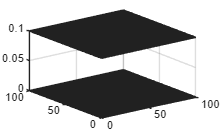


figure;
surf(xl, yl, zlb);
hold on;
surf(xl, yl, zlt);